## 路径读取

clear;
result_path = '/Volumes/NO NAME/新建文件夹/image';
result_list = dir(fullfile(result_path, '*.png'));
label_path = '/Volumes/NO NAME/新建文件夹/label';                 
label_list = dir(fullfile(label_path, '*.png'));
save_path = '/Volumes/NO NAME/新建文件夹/result';
[status, msg] = mkdir(save_path);
image_num = size(result_list, 1);
sz = 256;
map = [0, 0, 0; 0.4940, 0.1840, 0.5560; 0.4660, 0.6740, 0.1880; 1, 1, 1];

## 修改四值

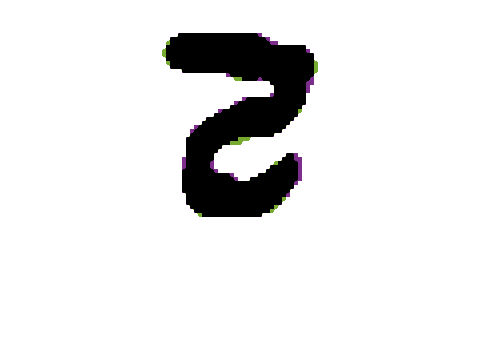

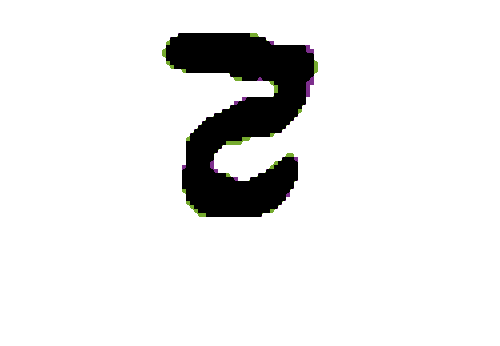

if image_num > 0
    for i = 1 : image_num
        
        result_name = result_list(i).name;
        label_name = label_list(i).name;
        
        result = imread(fullfile(result_path, result_name));
        
        if numel(size(result)) == 3
            result_reg1 = imbinarize(rgb2gray(result));
        elseif max(result, [], 'all') > 1
            result_reg1 = imbinarize(result);
        else
            result_reg1 = result;
        end
        
        result_reg2 = im2uint8(imresize(result_reg1, [sz, sz]));
        
        label = imread(fullfile(label_path, label_name));
        
        if numel(size(label)) == 3
            label_reg1 = imbinarize(rgb2gray(label));
        elseif max(label, [], 'all') > 1
            label_reg1 = imbinarize(label);
        else
            label_reg1 = label;
        end
        
        label_reg2 = im2uint8(imresize(label_reg1, [sz, sz]));
        
        for i = 1 : sz
            
            for j = 1 : sz
                
                if result_reg2(i, j) == 0 && label_reg2(i, j) == 0
                    result_reg2(i, j) = 0;
                elseif result_reg2(i, j) == 0 && label_reg2(i, j) == 255
                    result_reg2(i, j) = 1;
                elseif result_reg2(i, j) == 255 && label_reg2(i, j) == 0
                    result_reg2(i, j) = 2;
                elseif result_reg2(i, j) == 255 && label_reg2(i, j) == 255
                    result_reg2(i, j) = 3;
                end
                
            end            
            
        end
        figure;imshow(result_reg2, map);
        imwrite(result_reg2, map, fullfile(save_path, result_name));

    end
end